# tutorial1_PoissonGLM.m

## Housekeeping

clear
close all

set(0, 'DefaultAxesFontName', 'Arial');
set(0, 'DefaultAxesFontSize', 14);
set(0, 'DefaultLineLineWidth', 2);

%
% This is a tutorial illustrating the fitting of a linear-Gaussian
% Generalized Linear Model (GLM) — which is also known as linear
% least-squares regression model — as well as a Poisson GLM
% — aka  "linear-nonlinear-Poisson" model — to retinal ganglion cell spike
% trains stimulated with binary temporal white noise. 
%
% DATASET: this tutorial is designed to run with retinal ganglion cell
% spike train data from Uzzell & Chichilnisky 2004. The dataset can be 
% downloaded here:
%    http://pillowlab.princeton.edu/data/data_RGCs.zip
% The dataset is provided for tutorial purposes only, and should not be
% distributed or used for publication without express permission from EJ
% Chichilnisky (ej@stanford.edu). 
%
% Last updated: Mar 10, 2020 (JW Pillow)

## How to use this tutorial:

=========================

This is an interactive tutorial designed to walk you through the steps of fitting two classic models (linear-Gaussian GLM and Poisson GLM) to spike train data. It is organized into 'sections' that can be executed one after the other using keyboard shortcuts. The relevant shortcuts are: 

1. ctrl-enter - execute the current section 

2. ctrl-downarrow - move to the next section 

3. ctrl-uparrow - move to the prev section (if you want to go back up). 

4. ctrl-shift-enter - execute current section and move to the next

I strongly recommend learning to use these shortcuts and avoid using the mouse to select the "run this section" commands from the "editor" tab above. The mouse is a huge waste of time!

% In the following, I recommend positioning the figure window once it
% appears in a place where you can easily see it (e.g., 'docked' beside or
% above the editor / command windows, or else in its own place on the
% screen), with no other matlab windows you need on top of it or underneath
% it. Each section of the tutorial will overwrite the figure window, so
% once you get it positioned correctly there will be no need to  lift your
% hands from the keyboard. Just click cmd-enter to execute each section,
% read the relevant code and make changes as desired, and then cmd-down to
% go to the next section. And repeat. The figure window will always display
% the plots made in the current section, so there's no need to go clicking
% through multiple windows to find the one you're looking for!

## ==== 1. Load the raw data ============

% ------------------------------------------------------------------------
% Be sure to unzip the data file data_RGCs.zip
% (http://pillowlab.princeton.edu/data/data_RGCs.zip) and place it in 
% this directory before running the tutorial.  
% Or substitute your own dataset here instead!
% ------------------------------------------------------------------------
% (Data from Uzzell & Chichilnisky 2004):
datdir = 'data_RGCs/';  % directory where stimulus lives
load([datdir, 'Stim']);    % stimulus (temporal binary white noise)
load([datdir,'stimtimes']); % stim frame times in seconds (if desired)
load([datdir, 'SpTimes']); % load spike times (in units of stim frames)

% Pick a cell to work with
cellnum = 1; % (1-2 are OFF cells; 3-4 are ON cells).
spike_times = SpTimes{cellnum};
% -------------------------------------------------------------------------

% Compute some basic statistics on the data
time_bin_size = (stimtimes(2)-stimtimes(1)); % time bin size for stimulus (s)
monitor_refresh_rate = 1/time_bin_size; % Refresh rate of the monitor
num_time_bins = size(Stim,1); % number of time bins in stimulus
num_spikes = length(spike_times); % number of spikes

% Print out some basic info
fprintf('--------------------------\n');

--------------------------


fprintf('Loaded RGC data: cell %d\n', cellnum);

Loaded RGC data: cell 1


fprintf('Number of stim frames: %d  (%.1f minutes)\n',...
    num_time_bins, num_time_bins*time_bin_size/60);

Number of stim frames: 144051  (20.0 minutes)


fprintf('Time bin size: %.1f ms\n', time_bin_size*1000);

Time bin size: 8.3 ms


fprintf('Number of spikes: %d (mean rate=%.1f Hz)\n\n', num_spikes,...
    num_spikes/num_time_bins*monitor_refresh_rate);

Number of spikes: 31528 (mean rate=26.2 Hz)



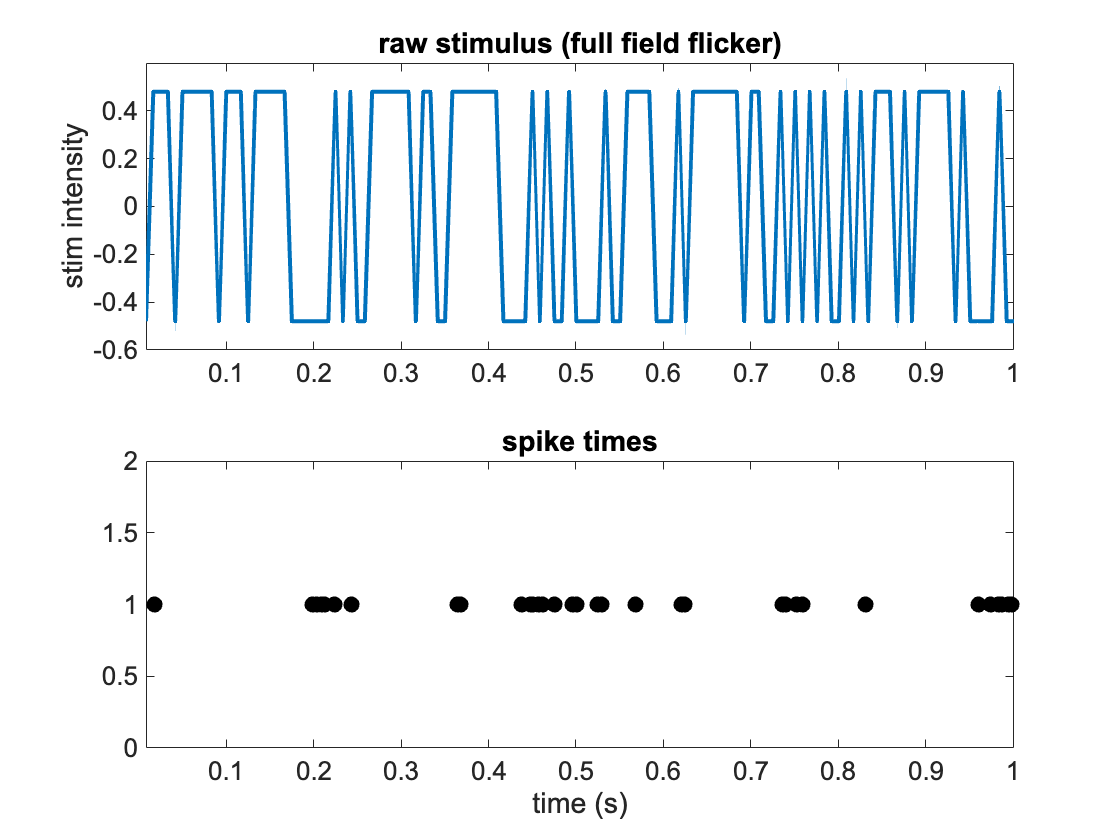


% Let's visualize some of the raw data
subplot(2,1,1);
bins_to_plot = 1:120; % bins of stimulus to plot
x_axis = bins_to_plot*time_bin_size; % time bins of stimulus
plot(x_axis,Stim(bins_to_plot), 'linewidth', 2);  axis tight;
title('raw stimulus (full field flicker)');
ylabel('stim intensity');
ylim([-0.6, 0.6])

subplot(2,1,2);
spike_time_plot = spike_times((spike_times>=x_axis(1))&(spike_times<x_axis(end)));
plot(spike_time_plot, 1, 'ko', 'markerfacecolor', 'k');
set(gca,'xlim', x_axis([1 end]));
title('spike times'); xlabel('time (s)');

## ==== 2. Bin the spike train =====

For now we will assume we want to use the same time bin size as the time bins used for the stimulus. Later, though, we'll wish to vary this.

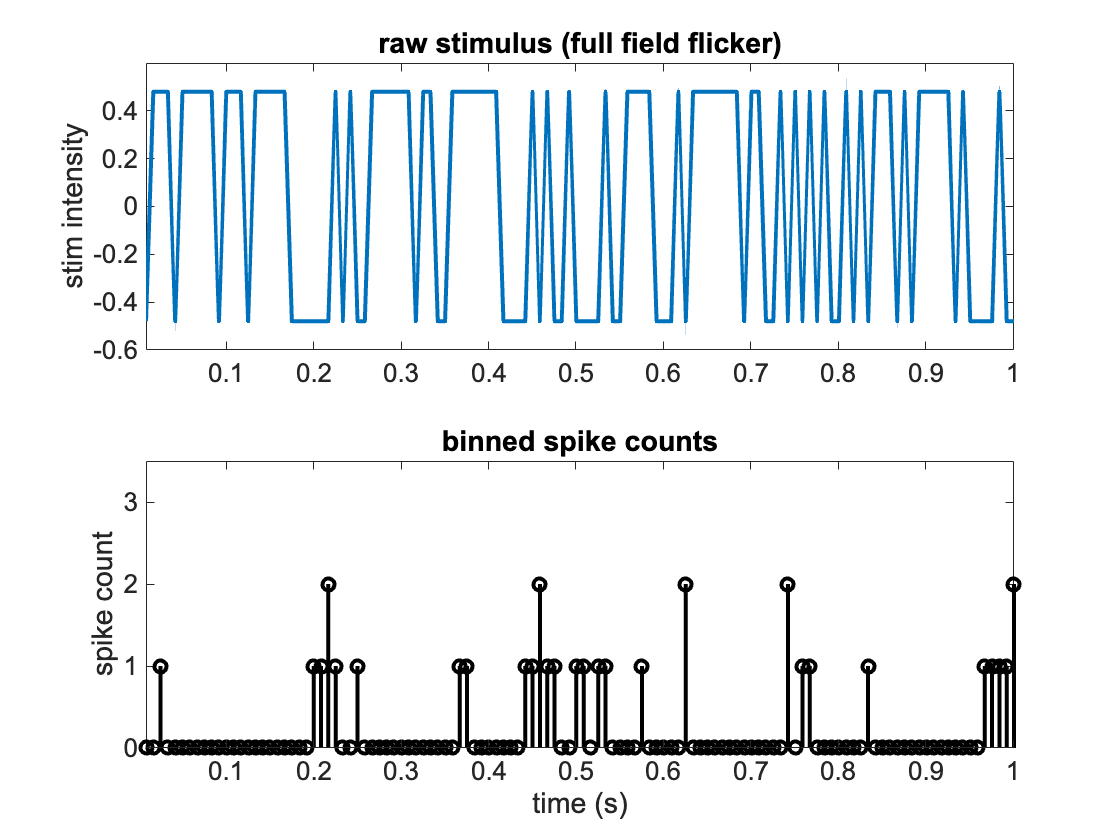

time_bin_centers = (.5:num_time_bins)*time_bin_size; % time bin centers for spike train binnning
spikes = hist(spike_times,time_bin_centers)';  % binned spike train

% Replot the responses we'll putting into our regression as counts
subplot(2,1,2);
stem(x_axis,spikes(bins_to_plot), 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');
set(gca,'xlim', x_axis([1 end]), 'ylim', [0 3.5]);

## ==== 3. Build the design matrix: slow version ======

This is a necessary step before we can fit the model: assemble a matrix that contains the relevant regressors for each time bin of the response, known as a design matrix. Each row of this matrix contains the relevant stimulus chunk for predicting the spike count at a given time bin

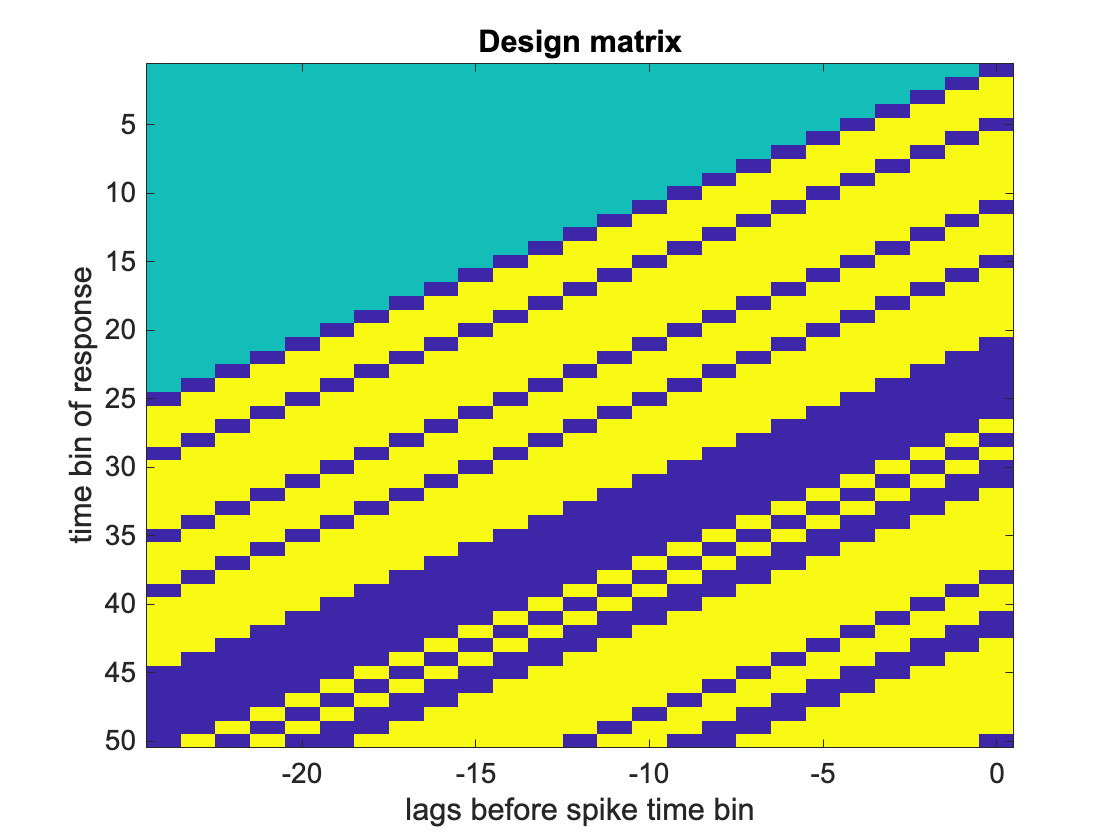

% Set the number of time bins of stimulus to use for predicting spikes
prediction_bins = 25;  % Try varying this, to see how performance changes!

% Build the design matrix: Slow version
paddedStim = [zeros(prediction_bins-1,1); Stim]; % pad early bins of stimulus with zero
design_matrix = zeros(num_time_bins,prediction_bins);
for j = 1:num_time_bins
    design_matrix(j,:) = paddedStim(j:j+prediction_bins-1)'; % grab last 'nkt' bins of stmiulus and insert into this row
end

% Let's visualize a small part of the design matrix just to see it
clf; imagesc(-prediction_bins+1:0, 1:50, design_matrix(1:50,:));
xlabel('lags before spike time bin');
ylabel('time bin of response');
title('Design matrix');


% Notice it has a structure where every row is a shifted copy of the row
% above, which comes from the fact that for each time bin of response,
% we're grabbing the preceding 'nkt' bins of stimulus as predictor

## 3b. Build the design matrix: fast version

% Of course there's a faster / more elegant way to do this. The design
% matrix here is known as a 'Hankel' matrix, which is the same as a
% Toeplitz matrix flipped left to right. A Hankel matrix is entirely
% determined by its first column and bottom row.  (Type 'help hankel', to
% learn more about this function).

% Build design matrix without using a for loop
paddedStim = [zeros(prediction_bins-1,1); Stim]; % pad early bins of stimulus with zero
design_matrix = hankel(paddedStim(1:end-prediction_bins+1),...
    Stim(end-prediction_bins+1:end));

% (You can check for you like that this gives the same matrix as the one
% created above!)

imagesc(-prediction_bins+1:0, 1:50, design_matrix(1:50,:));
xlabel('lags before spike time bin');
ylabel('time bin of response');
title('Design matrix');

## === 4. Compute and visualize the spike-triggered average (STA) ====

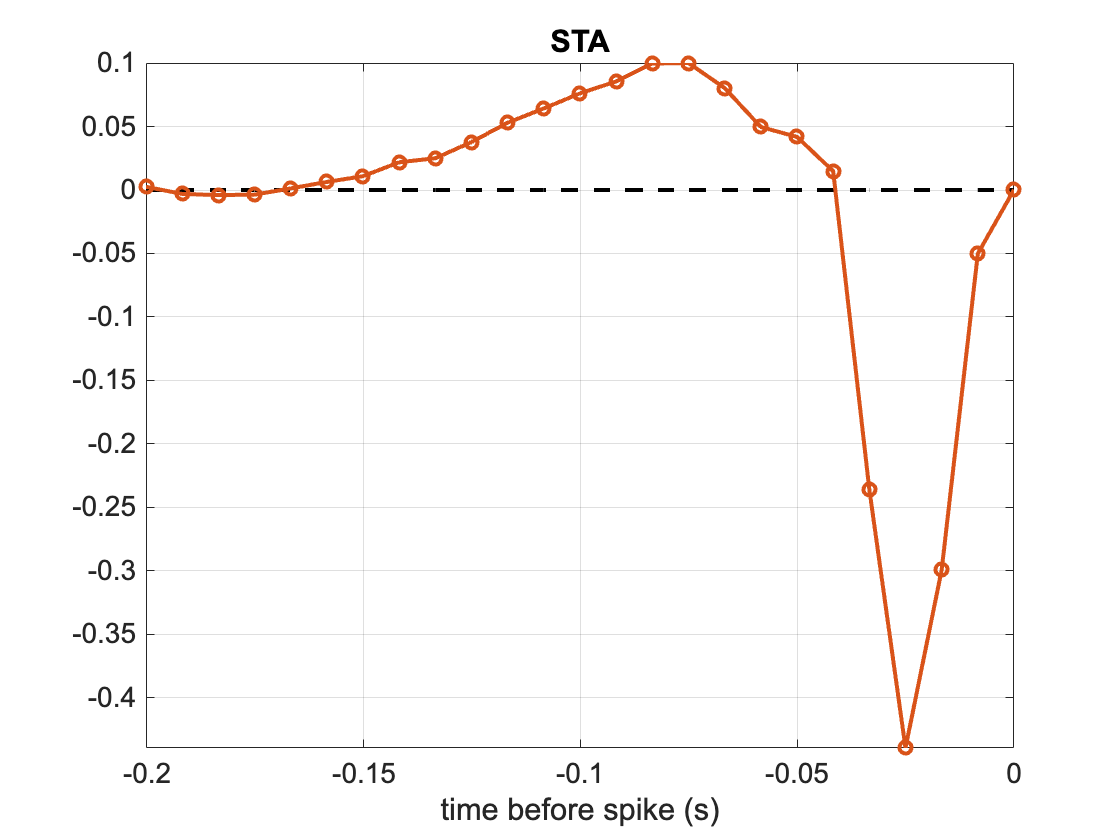

% When the stimulus is Gaussian white noise, the STA provides an unbiased
% estimator for the filter in a GLM / LNP model (as long as the nonlinearity
% results in an STA whose expectation is not zero; feel free 
% to ignore this parenthetical remark if you're not interested in technical
% details. It just means that if the nonlinearity is symmetric, 
% eg. x^2, then this condition won't hold, and the STA won't be useful).

% In many cases it's useful to visualize the STA (even if your stimuli are
% not white noise), just because if we don't see any kind of structure then
% this may indicate that we have a problem (e.g., a mismatch between the
% design matrix and binned spike counts.)

% It's extremely easy to compute the STA now that we have the design matrix
sta = (design_matrix'*spikes)/num_spikes;

% Plot it
sta_bins = (-prediction_bins+1:0)*time_bin_size; % time bins for STA (in seconds)
plot(sta_bins,sta_bins*0, 'k--', sta_bins, sta, 'o-');
grid on;
axis tight;
title('STA'); 
xlabel('time before spike (s)');


% If you're still using cell #1, this should look like a biphasic filter
% with a negative lobe just prior to the spike time.

% (By contrast, if this looks like garbage then it's a good chance we did
% something wrong!)

## 4b. whitened STA (ML fit to filter for linear-Gaussian GLM)

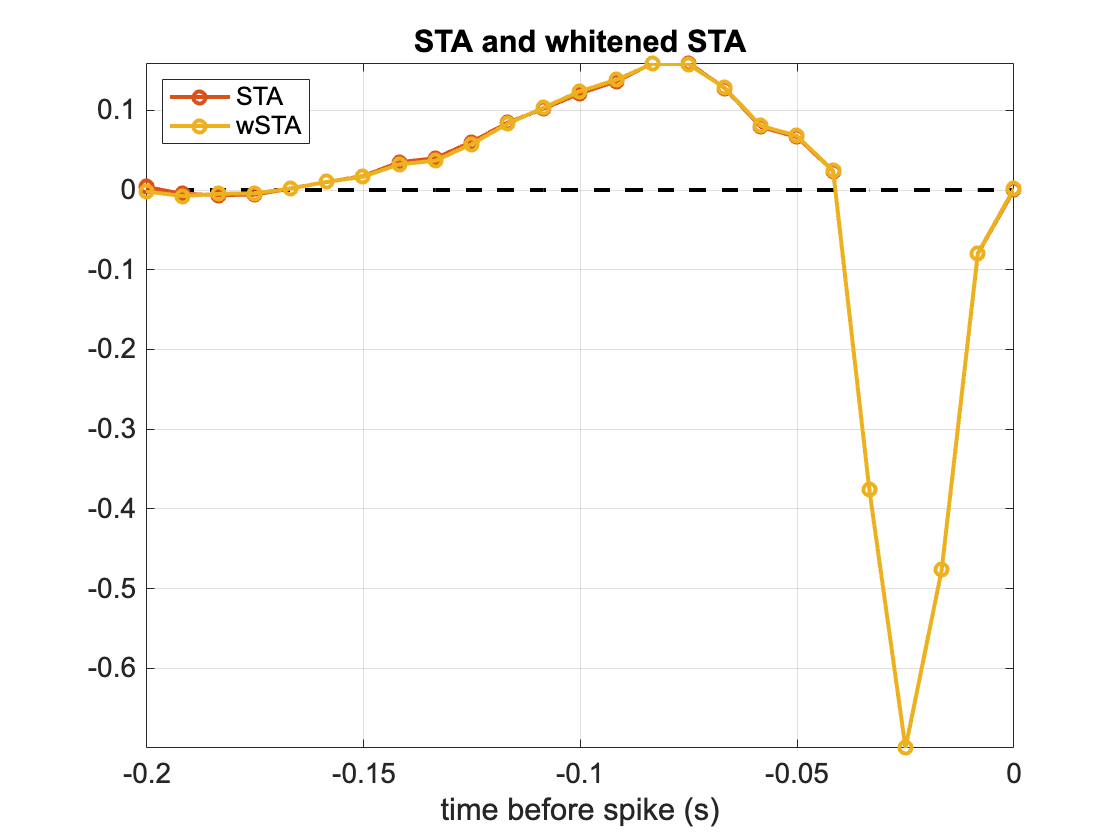

% If the stimuli are non-white, then the STA is generally a biased
% estimator for the linear filter. In this case we may wish to compute the
% "whitened" STA, which is also the maximum-likelihood estimator for the filter of a 
% GLM with "identity" nonlinearity and Gaussian noise (also known as
% least-squares regression). 
%
% If the stimuli have correlations this ML estimate may look like garbage
% (more on this later when we come to "regularization").  But for this
% dataset the stimuli are white, so we don't (in general) expect a big
% difference from the STA.  (This is because the whitening matrix
% (Xdsng'*Xdsgn)^{-1} is close to a scaled version of the identity.

% whitened STA
whitened_sta = (design_matrix'*design_matrix)\sta*num_spikes;
% or equivalently inv(Xdsgn'*Xdsgn)*(Xdsgn'*sps)
% this is just the least-squares regression formula!

% Let's plot them both (rescaled as unit vectors so we can see differences
% in their shape).
h = plot(sta_bins,sta_bins*0, '--k', sta_bins, sta./norm(sta), 'o-',...
    sta_bins, whitened_sta./norm(whitened_sta), 'o-');
grid on;
axis tight;
legend(h(2:3), 'STA', 'wSTA', 'location', 'northwest');
title('STA and whitened STA');
xlabel('time before spike (s)');

## 4c. Predicting spikes with a linear-Gaussian GLM

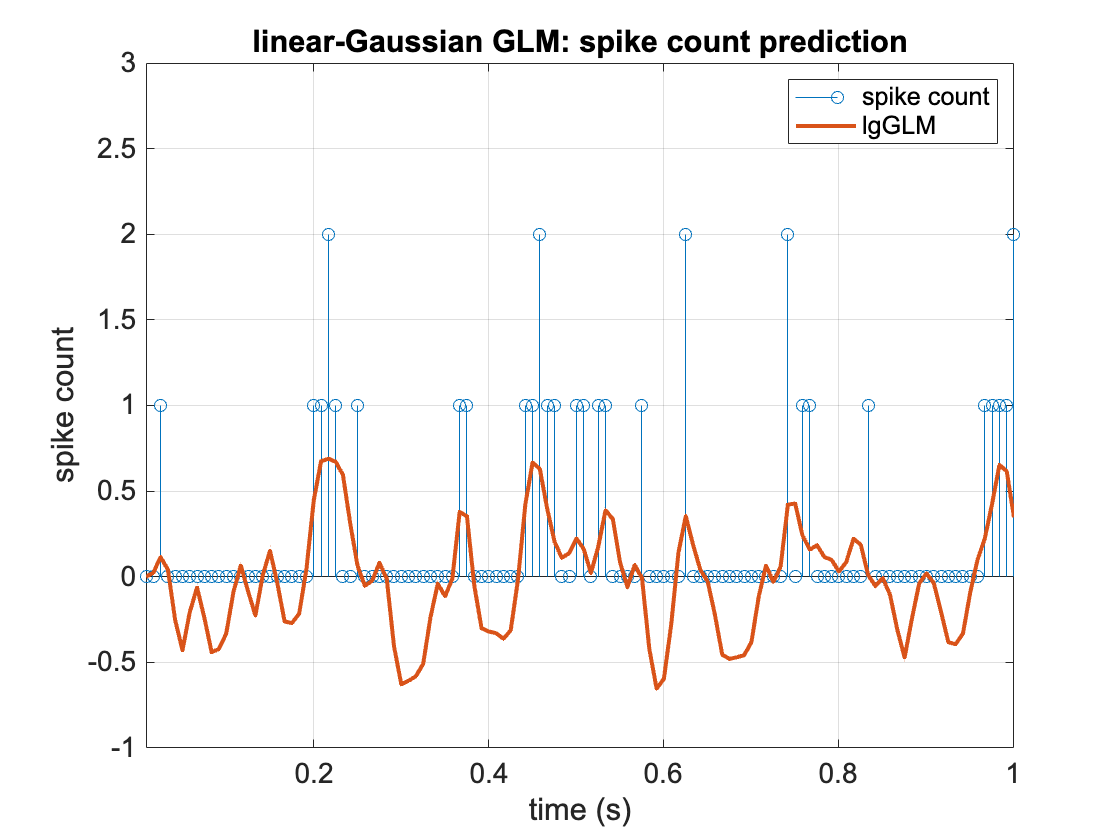

% The whitened STA can actually be used to predict spikes because it
% corresponds to a proper estimate of the model parameters (i.e., for a
% Gaussian GLM). Let's inspect this prediction

predicted_spikes_lgGLM = design_matrix*whitened_sta;  % predicted spikes from linear-Gaussian GLM

% Let's see how good this "prediction" is
% (Prediction in quotes because we are (for now) looking at the performance
% on training data, not test data... so it isn't really a prediction!)

% Plot real spike train and prediction
stem(x_axis,spikes(bins_to_plot)); 
hold on;
grid on;
plot(x_axis,predicted_spikes_lgGLM(bins_to_plot));
hold off;
title('linear-Gaussian GLM: spike count prediction');
ylabel('spike count');
xlabel('time (s)');
xlim(x_axis([1 end]));
ylim([-1,3]);
legend('spike count', 'lgGLM');

## 4d. Fitting and predicting with a linear-Gaussian-GLM with offset

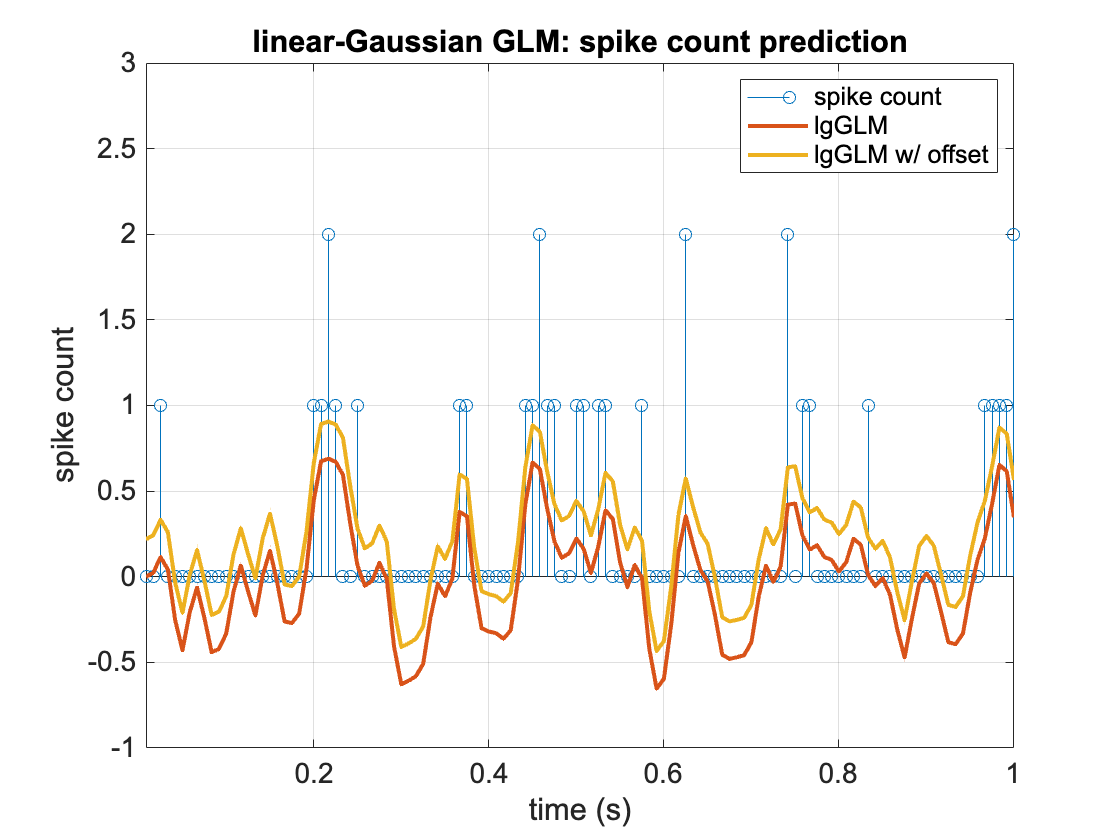

% Oops, one thing we forgot above was to include an offset or "constant"
% term in the design matrix, which will allow our prediction to have
% non-zero mean (since the stimulus here was normalized to have zero mean).

% Updated design matrix
design_matrix_2 = [ones(num_time_bins,1), design_matrix]; % just add a column of ones

% Compute whitened STA
ML_weights = (design_matrix_2'*design_matrix_2)\(design_matrix_2'*spikes); % this is just the LS regression formula
const = ML_weights(1); % the additive constant
whitened_sta2 = ML_weights(2:end); % the linear filter part

% Now redo prediction (with offset)
predicted_spikes_lgGLM2 = const + design_matrix*whitened_sta2;

% Plot this stuff
stem(x_axis,spikes(bins_to_plot));
hold on;
grid on;
plot(x_axis,predicted_spikes_lgGLM(bins_to_plot),...
    x_axis,predicted_spikes_lgGLM2(bins_to_plot)); 
hold off;
title('linear-Gaussian GLM: spike count prediction');
ylabel('spike count');
xlabel('time (s)');
xlim(x_axis([1 end]));
ylim([-1,3]);
legend('spike count', 'lgGLM', 'lgGLM w/ offset');


% Let's report the relevant training error (squared prediction error on
% training data) so far just to see how we're doing:
mean_sq_err_1 = mean((spikes-predicted_spikes_lgGLM).^2); % mean squared error, GLM no offset
mean_sq_err_2 = mean((spikes-predicted_spikes_lgGLM2).^2);% mean squared error, with offset
sq_err = mean((spikes-mean(spikes)).^2); % squared error of spike train

fprintf('Training perf (R^2): lin-gauss GLM, no offset: %.2f\n',1-mean_sq_err_1/sq_err);

Training perf (R^2): lin-gauss GLM, no offset: 0.13


fprintf('Training perf (R^2): lin-gauss GLM, w/ offset: %.2f\n',1-mean_sq_err_2/sq_err);

Training perf (R^2): lin-gauss GLM, w/ offset: 0.31


## ====== 5. Poisson GLM ====================

% Let's finally move on to the LNP / Poisson GLM!

% This is super-easy if we rely on built-in GLM fitting code
poisson_GLM_wts = glmfit(design_matrix,spikes,'poisson', 'constant', 'on');
poisson_GLM_const = poisson_GLM_wts(1); % constant ("dc term"); 
poisson_GLM_filt = poisson_GLM_wts(2:end); % stimulus filter

% The 'glmfit' function will fit a GLM for us. Here we have specified that
% we want the noise model to be Poisson. The default setting for the link
% function (the inverse of the nonlinearity) is 'log', so default
% nonlinearity is 'exp'). The last argument tells glmfit to include a
% constant offset parameter in the model, so we can use the 'Xdsgn' matrix
% instead of the 'Xdsgn2' matrix that contains 1's in the first row.
% 
% The above call is thus equivalent to having done:
% > pGLMwts = glmfit(Xdsgn2,sps,'poisson', 'link', 'log','constant','off');

% Compute predicted spike rate on training data
predicted_spikes_pGLM = exp(poisson_GLM_const + design_matrix*poisson_GLM_filt);
%  (equivalent to if we had just written exp(Xdsgn2*pGLMwts))/dtStim;

## 5b. Make plots showing and spike rate predictions

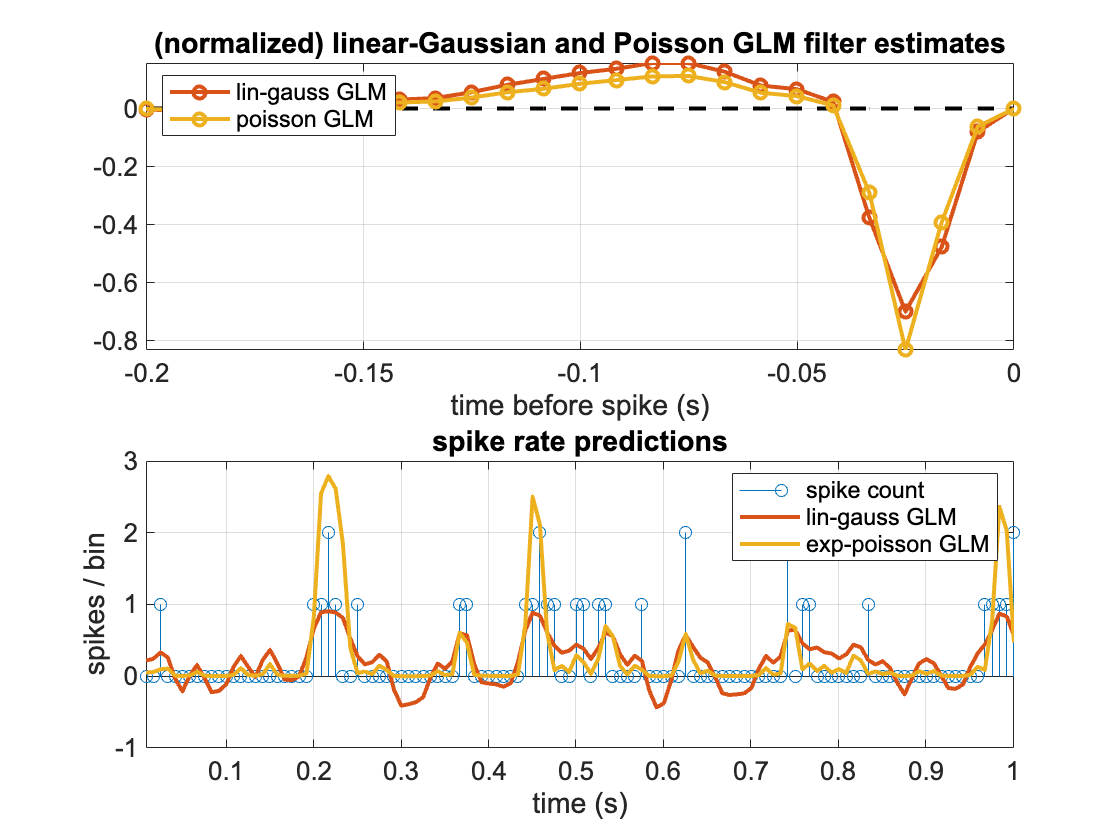

subplot(2,1,1);
h = plot(sta_bins,sta_bins*0, 'k--',...
    sta_bins, whitened_sta2./norm(whitened_sta2), 'o-',...
    sta_bins, poisson_GLM_filt./norm(poisson_GLM_filt), 'o-');
axis tight;
grid on;
legend(h(2:3), 'lin-gauss GLM', 'poisson GLM', 'location', 'northwest');
title('(normalized) linear-Gaussian and Poisson GLM filter estimates'); 
xlabel('time before spike (s)');

subplot(2,1,2);
stem(x_axis,spikes(bins_to_plot));
hold on;
grid on;
plot(x_axis,predicted_spikes_lgGLM2(bins_to_plot),...
    x_axis,predicted_spikes_pGLM(bins_to_plot)); 
hold off;
title('spike rate predictions');
ylabel('spikes / bin');
xlabel('time (s)');
xlim(x_axis([1 end]));
legend('spike count', 'lin-gauss GLM', 'exp-poisson GLM');


% Note the rate prediction here is in units of spikes/bin. If we wanted
% spikes/sec, we could divide it by bin size dtStim.

## 6. Non-parametric estimate of the nonlinearity

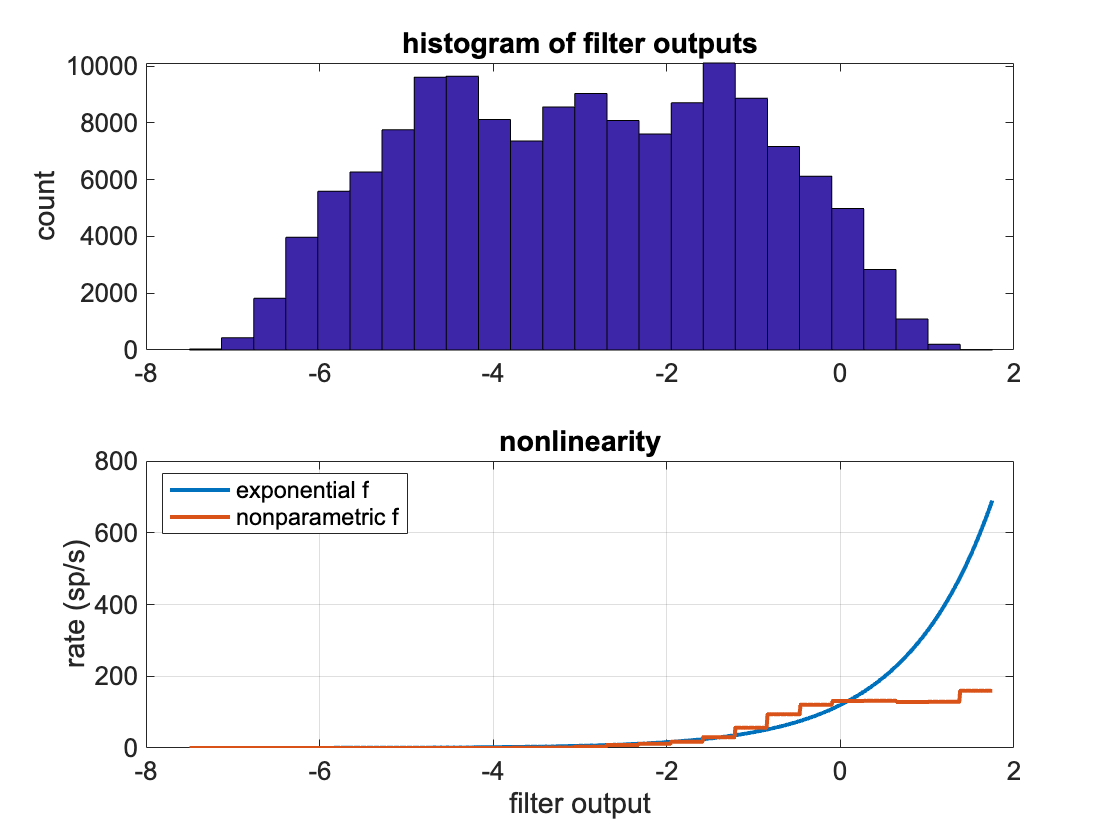

% The above fitting code assumes a GLM with an exponential nonlinearity
% (i.e., governing the mapping from filter output to instantaneous spike
% rate). We might wish to examine the adequacy of that assumption and make
% a "nonparametric" estimate of the nonlinearity using a more flexible
% class of functions.

% Let's use the family of piece-wise constant functions, which results in a
% very simple estimation procedure:

% 1. Bin the filter outputs
% 2. In each bin, compute the fraction of stimuli elicted spikes

% number of bins for parametrizing the nonlinearity f. (Try varying this!) 
num_bins_nonlin_f = 25; 

% compute filtered stimulus
raw_filter_output = poisson_GLM_const + design_matrix*poisson_GLM_filt;

% bin filter output and get bin index for each filtered stimulus
[counts,bin_edges,bin_ID] = histcounts(raw_filter_output,num_bins_nonlin_f); 

nonlin_f_x = bin_edges(1:end-1)+diff(bin_edges(1:2))/2; % use bin centers for x positions

% now compute mean spike count in each bin
nonlin_f_y = zeros(num_bins_nonlin_f,1); % y values for nonlinearity
for jj = 1:num_bins_nonlin_f
    nonlin_f_y(jj) = mean(spikes(bin_ID==jj));
end

nonlin_f_y = nonlin_f_y/time_bin_size; % divide by bin size to get units of sp/s;

% Now let's embed this in a function we can evaluate at any point
nonlin_fun = @(x)(interp1(nonlin_f_x,nonlin_f_y,x,'nearest','extrap'));

% Make plots
subplot(2,1,1); % Plot exponential and nonparametric nonlinearity estimate
bar(nonlin_f_x,counts, 'hist');
ylabel('count');
title('histogram of filter outputs');

subplot(2,1,2);
x_axis2 = bin_edges(1):.01:bin_edges(end);
plot(x_axis2,exp(x_axis2)/time_bin_size,...
    x_axis2,nonlin_fun(x_axis2));
grid on
xlabel('filter output');
ylabel('rate (sp/s)');
legend('exponential f', 'nonparametric f', 'location', 'northwest');
title('nonlinearity');


% What do you think of the exponential fit? Does this look like a good
% approximation to the nonparametric estimate of the nonlinearity?  Can you
% propose a better parametric nonlinearity to use instead?  
%
% Advanced exercise: write your own log-likelihood function that allows you
% to jointly optimize log-likelihood for the filter parameters and
% nonlinearity.  (By contrast, here we have optimized filter params under
% exponential nonlinearity and THEN fit the nonlinearity using these fixed
% filter parameters).  We could, for example, iteratively climb the
% log-likelihood as a function of filter params and nonlinearity params;
% this is a method known as "coordinate ascent").

## 7. Quantifying performance: log-likelihood

% Lastly, compute log-likelihood for the Poisson GLMs we've used so far and
% compare performance.

% LOG-LIKELIHOOD (this is what glmfit maximizes when fitting the GLM):
% --------------
% Let s be the spike count in a bin and r is the predicted spike rate
% (known as "conditional intensity") in units of spikes/bin, then we have:   
%
%        Poisson likelihood:      P(s|r) = r^s/s! exp(-r)  
%     giving log-likelihood:  log P(s|r) =  s log r - r   
%
% (where we have ignored the -log s! term because it is independent of the
% parameters). The total log-likelihood is the summed log-likelihood over
% time bins in the experiment.

% 1. for GLM with exponential nonlinearity
predicted_spikes_pGLM = exp(poisson_GLM_const...
    + design_matrix*poisson_GLM_filt); % rate under exp nonlinearity

log_likelihood_expGLM = spikes'*log(predicted_spikes_pGLM)...
    - sum(predicted_spikes_pGLM);

% 2. for GLM with non-parametric nonlinearity
ratepred_pGLMnp = time_bin_size*nonlin_fun(poisson_GLM_const +...
    design_matrix*poisson_GLM_filt); % rate under nonpar nonlinearity

log_likelihood_npGLM = spikes(spikes>0)'*...
    log(ratepred_pGLMnp(spikes>0)) - sum(ratepred_pGLMnp);

% Now compute the rate under "homogeneous" Poisson model that assumes a
% constant firing rate with the correct mean spike count.
ratepred_const = num_spikes/num_time_bins;  % mean number of spikes / bin

log_likelihood_0 = num_spikes*log(ratepred_const) -...
    num_time_bins*ratepred_const;

% Single-spike information:
% ------------------------
% The difference of the loglikelihood and homogeneous-Poisson
% loglikelihood, normalized by the number of spikes, gives us an intuitive
% way to compare log-likelihoods in units of bits / spike.  This is a
% quantity known as the (empirical) single-spike information.
% [See Brenner et al, "Synergy in a Neural Code", Neural Comp 2000].

% You can think of this as the number of bits (number of yes/no questions
% that we can answer) about the times of spikes when we know the spike rate
% output by the model, compared to when we only know the (constant) mean
% spike rate. 

singlespike_info_expGLM = (log_likelihood_expGLM - log_likelihood_0)/...
    num_spikes/log(2);

singlespike_info_npGLM = (log_likelihood_npGLM - log_likelihood_0)/...
    num_spikes/log(2);

% (if we don't divide by log 2 we get it in nats)

fprintf('\n empirical single-spike information:\n ---------------------- \n');


 empirical single-spike information:
 ---------------------- 


fprintf('exp-GLM: %.2f bits/sp\n',singlespike_info_expGLM);

exp-GLM: 1.42 bits/sp


fprintf(' np-GLM: %.2f bits/sp\n',singlespike_info_npGLM);

 np-GLM: 1.52 bits/sp


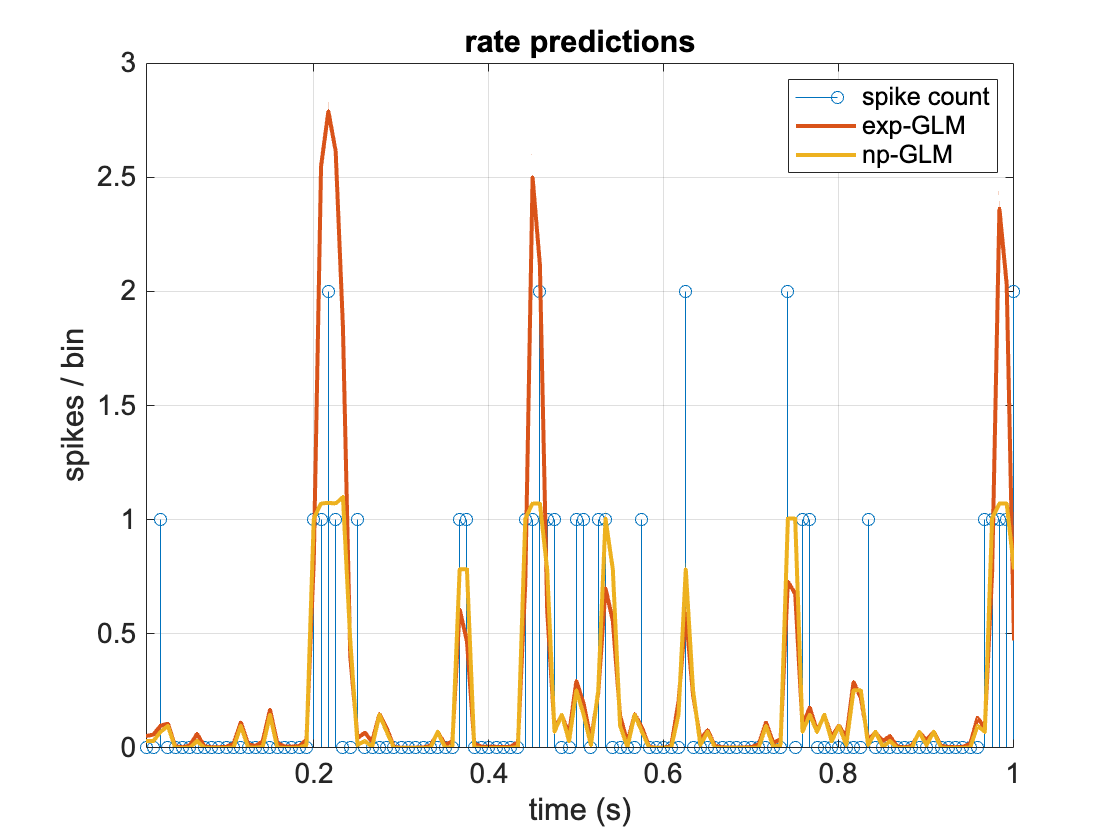


% Let's plot the rate predictions for the two models 
% --------------------------------------------------
subplot(1,1,1);
stem(x_axis,spikes(bins_to_plot));
hold on;
grid on;
plot(x_axis,predicted_spikes_pGLM(bins_to_plot),...
    x_axis,ratepred_pGLMnp(bins_to_plot)); 
hold off;
title('rate predictions');
ylabel('spikes / bin');
xlabel('time (s)');
xlim(x_axis([1 end]));
legend('spike count', 'exp-GLM', 'np-GLM');

## 8. Quantifying performance: AIC

% Akaike information criterion (AIC) is a method for model comparison that
% uses the maximum likelihood, penalized by the number of parameters.
% (This allows us to compensate for the fact that models with more
% parameters can in general achieve higher log-likelihood. AIC determines
% how big this tradeoff should be in terms of the quantity:
%        AIC = - 2*log-likelihood + 2 * number-of-parameters

% The model with lower AIC is their likelihood (at the ML estimate), 
% penalized by the number of parameters  

AIC_expGLM = -2*log_likelihood_expGLM + 2*(1+prediction_bins); 
AIC_npGLM = -2*log_likelihood_npGLM + 2*(1+prediction_bins+num_bins_nonlin_f);

fprintf('\n AIC comparison:\n ---------------------- \n');


 AIC comparison:
 ---------------------- 


fprintf('exp-GLM: %.1f\n',AIC_expGLM);

exp-GLM: 96913.9


fprintf(' np-GLM: %.1f\n',AIC_npGLM);

 np-GLM: 92706.9


fprintf('\nAIC diff (exp-np)= %.2f\n',AIC_expGLM-AIC_npGLM);


AIC diff (exp-np)= 4206.97



if AIC_expGLM < AIC_npGLM
    fprintf('AIC supports exponential-nonlinearity!\n');
else
    fprintf('AIC supports nonparametric nonlinearity!\n');
    % (despite its greater number of parameters)
end

AIC supports nonparametric nonlinearity!



% Caveat: technically the AIC should be using the maximum of the likelihood
% for a given model.  Here we actually have an underestimate of the
% log-likelihood for the non-parameteric nonlinearity GLM because
% because we left the filter parameters unchanged from the exponential-GLM.
% So a proper AIC comparison (i.e., if we'd achieved a true ML fit) would
% favor the non-parametric nonlinearity GLM even more!

% Exercise: go back and increase 'nfbins', the number of parameters (bins)
% governing the nonparametric nonlinearity. If you increase it enough, you
% should be able to flip the outcome so exponential nonlinearity wins.

% (Note: in the third tutorial we'll use cross-validation to properly
% evaluate the goodness of the fit of the models, e.g., allowing us to
% decide how many bins of stimulus history or how many bins to use for the
% non-parametric nonlinearity, or how to set regularization
% hyperparameters. The basic idea is to split data into training and test
% sets.  Fit the parameters on the training set, and compare models by
% evaluating log-likelihood on test set.)

## 9. Simulating the GLM / making a raster plot

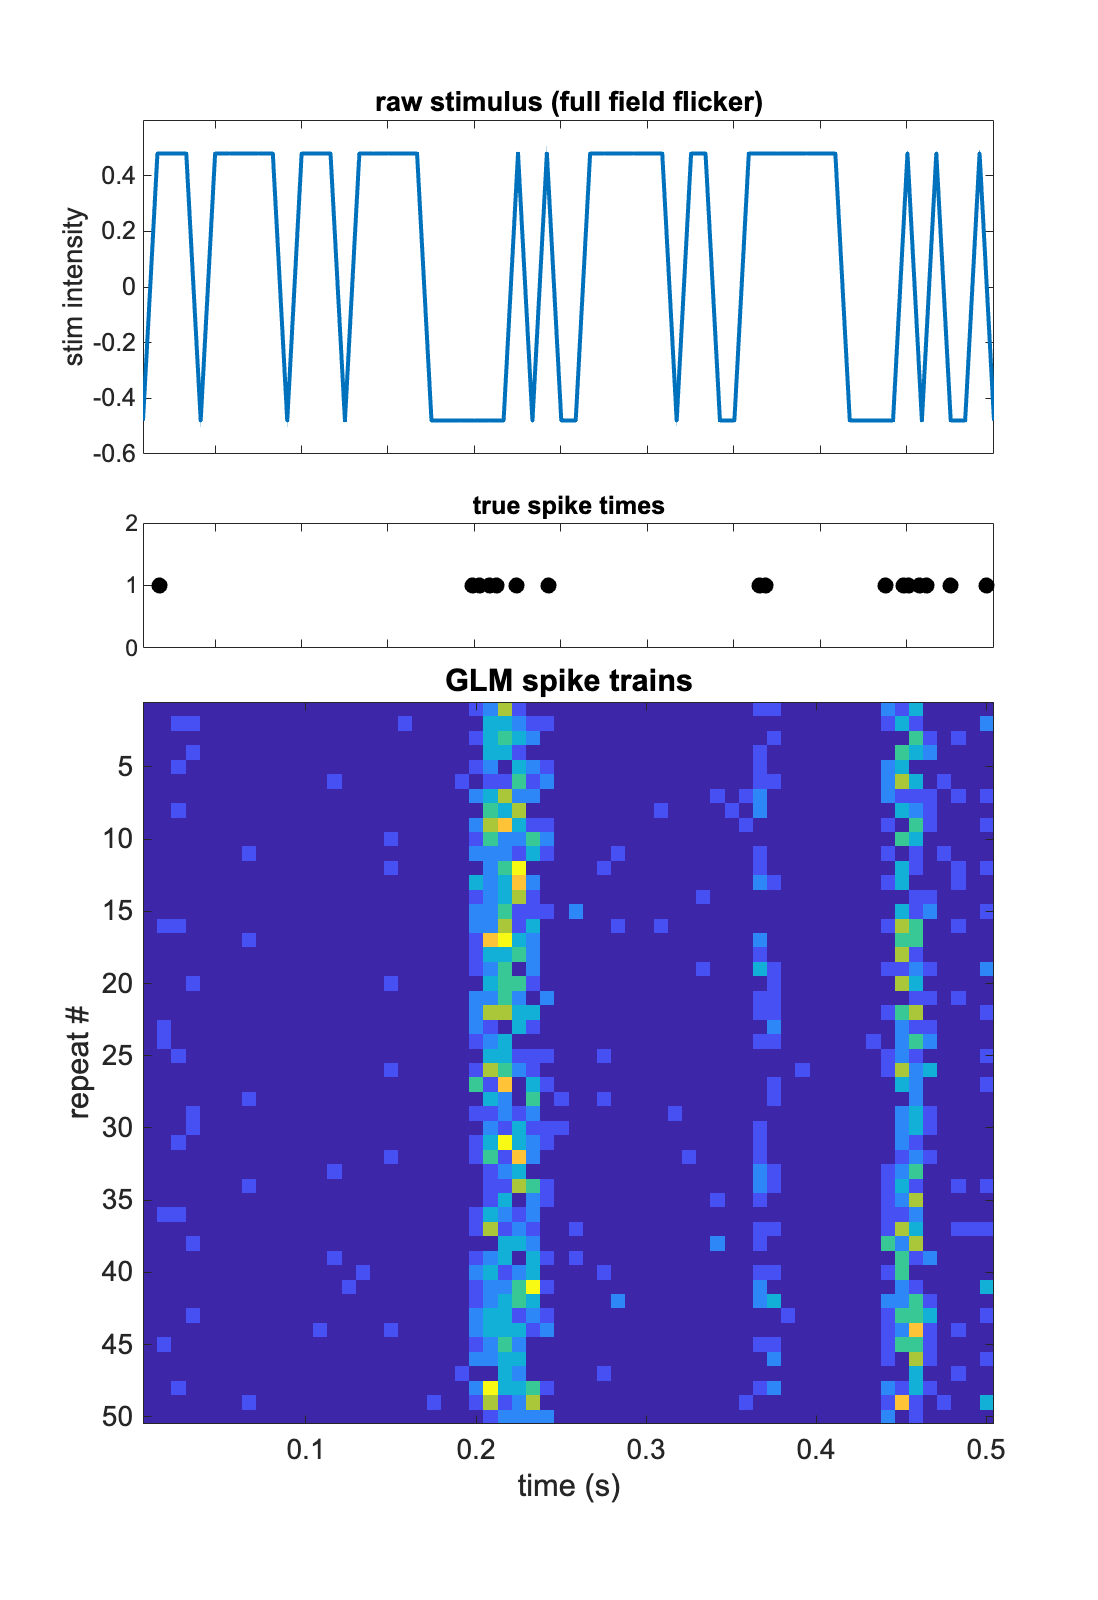

% Lastly, let's simulate the response of the GLM to a repeated stimulus and
% make raster plots 

bins_to_plot = 1:60; % time bins of stimulus to use
x_axis = bins_to_plot*time_bin_size; % time indices for these stimuli
stim_repeat = Stim(bins_to_plot); % repeat stimulus 
num_rpts = 50;  % number of repeats
firing_rate = exp(poisson_GLM_const+design_matrix(bins_to_plot,:)...
    *poisson_GLM_filt); % firing rate in each bin

% Or uncomment this line to use the non-parametric nonlinearity instead:
%frate = dtStim*fnlin(pGLMconst+Xdsgn(iiplot,:)*pGLMfilt);% firing rate in each bin

% First, plot stimulus and true spikes
large_fig = figure("Position", [0, 0, 1200/2, 1750/2]);

subplot(7,1,1:2);
plot(x_axis,stim_repeat);
axis tight;
title('raw stimulus (full field flicker)');
ylabel('stim intensity'); 
ylim([-0.6, 0.6])
xticklabels({});

subplot(7,1,3);
spike_time_plot = spike_times((spike_times>=x_axis(1))&(spike_times<x_axis(end)));
plot(spike_time_plot, 1, 'ko', 'markerfacecolor', 'k');
xlim(x_axis([1 end]));
title('true spike times');
xticklabels({});

% Simulate spikes using draws from a Bernoulli (coin flipping) process
spike_counts = poissrnd(repmat(firing_rate',num_rpts,1)); % sample spike counts for each time bin
subplot(7,1,4:7);
imagesc(x_axis,1:num_rpts, spike_counts);
ylabel('repeat #');
xlabel('time (s)');
title('GLM spike trains');

## Optional: redo using finer time bins, so we get maximum 1 spike per bin

upsampfactor = 100; % divide each time bin by this factor
dt_fine = time_bin_size/upsampfactor; % use bins 100 time bins finer
tt_fine = dt_fine/2:dt_fine:x_axis(end);

% Compute the fine-time-bin firing rate (which must be scaled down by bin width)
frate_fine = interp1(x_axis,firing_rate,tt_fine,'nearest','extrap')'/upsampfactor;

% now draw fine-timescale spike train
spcounts_fine = poissrnd(repmat(frate_fine',num_rpts,1)); % sample spike counts for each time bin

% Make plot
subplot(7,1,4:7);

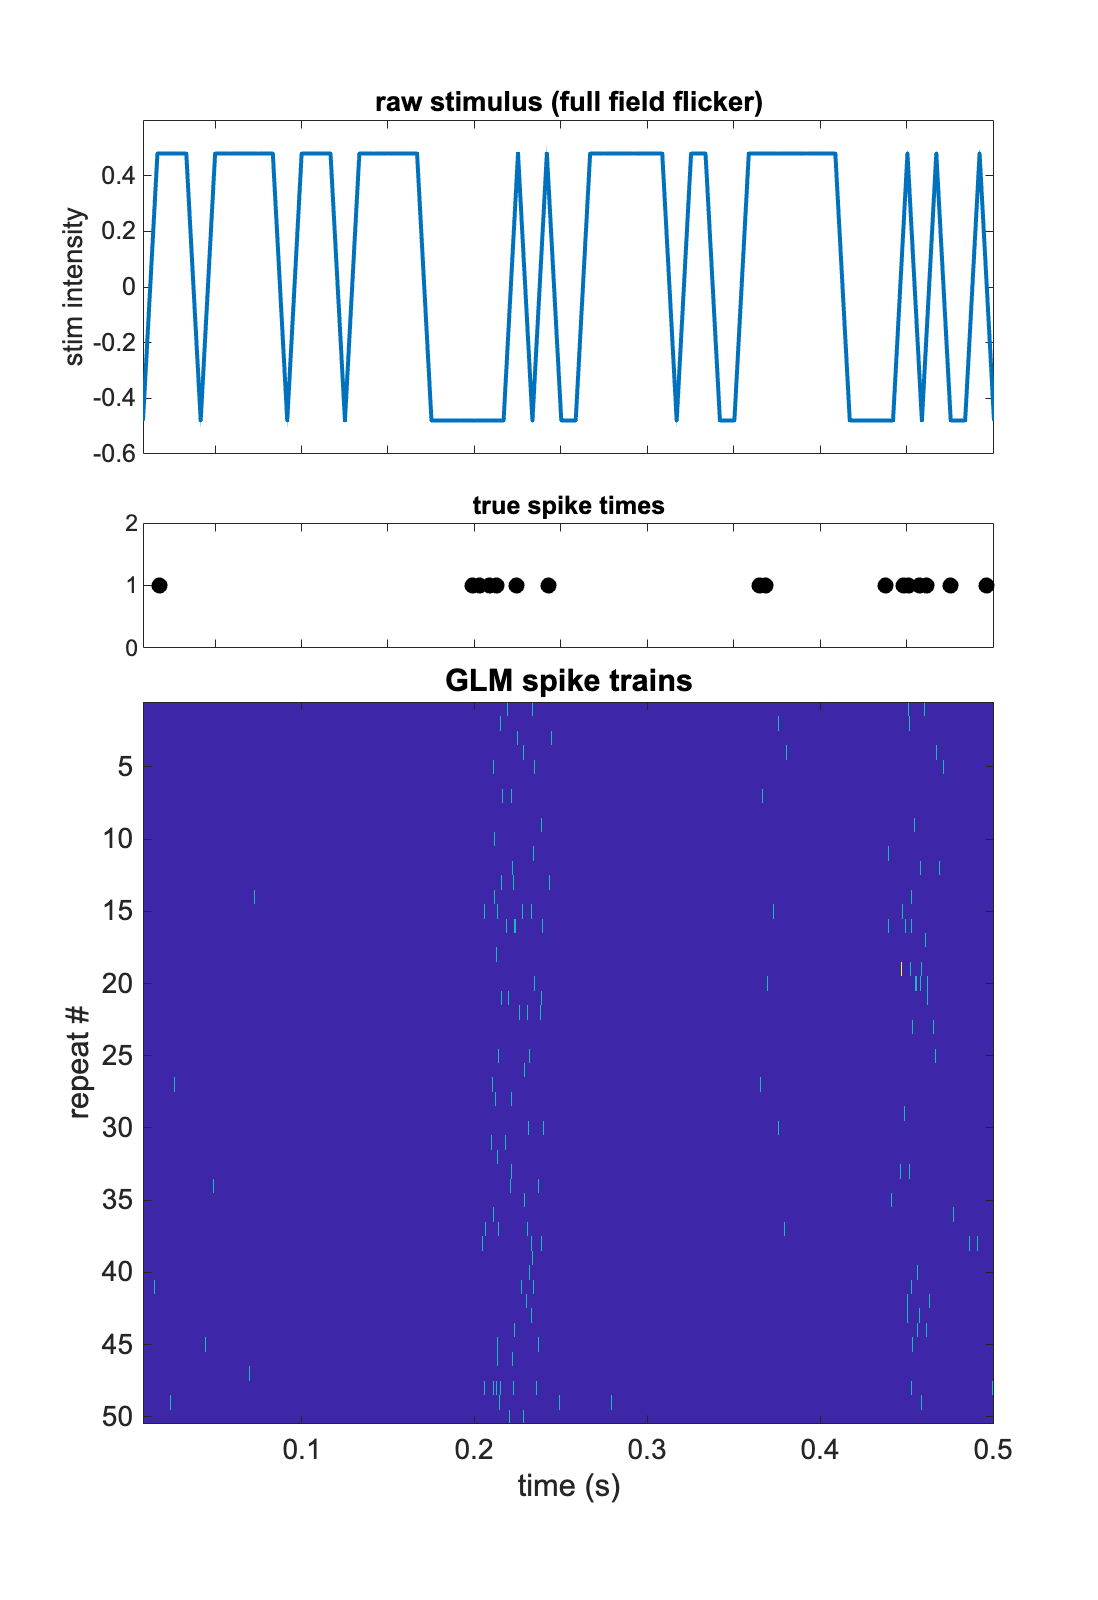

imagesc(x_axis,1:num_rpts, spcounts_fine);
ylabel('repeat #');
xlabel('time (s)');
title('GLM spike trains');

## Suggested Exercises (advanced)

-------------------------------

1) Go back and try it out for the other three neurons! (Go to block 1 and change the variable 'cellnum' to 2, 3, or 4.)

2) Write your own code to do maximum likelihood estimation of the filter and the nonlinearity. Your function should take in the parameters for the filter and the nonlinearity, and compute the Poisson log-likelihood function, the log Probability of the spike responses given the stimuli and the parameters. A nice way to parametrize the nonlinearity is with a linear combination of basis functions, e.g. f(x) = sum_i w_i * f_i(x) where f_i(x) is the i'th basis function and w_i is the weight on that basis function. You can choose the f_i to be Gaussian bumps or sigmoids, i.e. f_i(x) = 1./(1+exp(-x - c_i)) where c_i is the shift for the i'th basis function.

Another alternative (that will prevent negative firing rates) is to parameterize the log-firing rate with a linear combination of basis functions, e.g. log(f(x)) = sum_i w_i * f_i(x) meaning that f(x) = exp(sum_i w_i * f_i(x)) Now your weights can be negative or positive without fear of generating negative values (which will cause your negative log-likelihood function to give nans or -infs. 